# Antenna Pattern Lab

In this lab, we capture the Phase antenna pattern by steering the beam and looking at the captured signal magnitude at each steering angle.

Before running this lab, ensure that you have already collected the calibration weights using the "Calibrate Antenna" livescript.

## Setup

First, put the HB100 transmitter as close to boresight as possible. For this lab to work, the transmitter has to start at boresight.

Run the following to clear the workspace.

clear;
close all;
warning('off','MATLAB:system:ObsoleteSystemObjectMixin');

We also load the calibration weights which are applied so that the beam pattern matches our expectations.

load('CalibrationWeights.mat','calibrationweights');

### Identify HB100 Frequency

Before collecting any data, we need to identify the operating frequency of the HB100. Run the following script to do so.

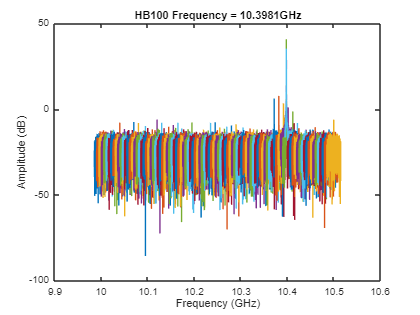

fc_hb100 = findTxFrequency();

### Create Antenna Interactor

The antenna interactor object helps us to interact with the phaser board to steer the beam and collect data. Create this object so that we can control the antenna.

ai = AntennaInteractor(fc_hb100,calibrationweights);

### Create Antenna Model

In order to generate amplitudes and phases to change the antenna pattern behavior, we need to have an approximate model of the antenna array. The Phaser antenna array is made up of two four-element uniform linear arrays (ULA). The antenna element spacing is 1/2 wavelength at a frequency of 10.39875 GHz. We create this antenna model below.

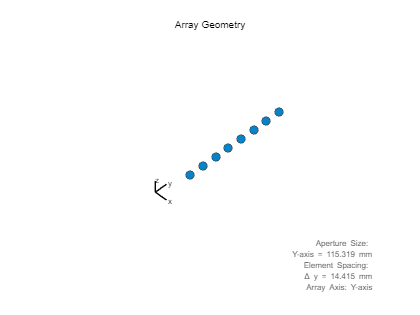

lambda = freq2wavelen(10.39875e9);
spacing = lambda/2;
array = phased.ULA(NumElements=8,ElementSpacing=spacing);
elementLocation = array.getElementPosition();
viewArray(array);

## Collect Antenna Pattern

We first collect the antenna pattern by steering the phases at each antenna element so that the main beam points to different angles from -90 to 90 degrees in azimuth while leaving the HB100 stationary at approximately boresight.

The ideal approach to capture the true pattern would be to leave the beam pattern pointing towards boresight and move the HB100 to known fixed angles and measure the magnitude of the collected signal. However, because this is difficult to acheive, we instead steer the beam leaving the HB100 at a fixed location.

Try running this script and moving the transmitter to different angles to see how the collected beam pattern changes.

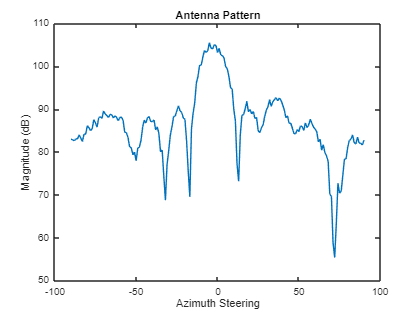

azAngles = -90:90;
nAngles = length(azAngles);
pattern = zeros(1,nAngles);
for i = 1:nAngles
    % Get the steering vector that directs the beam in the desired
    % direction
    steerAngle = azAngles(i);
    steerweights = steervec(elementLocation/freq2wavelen(fc_hb100),[steerAngle;0]);

    % Set the analog beamforming weights on the Phaser board to steer the beam,
    % adjusting for calibration. First we have to rearrange them into two
    % columns - one for each subarray.
    analogsteer = analogWeightsCalAdjustment([steerweights(1:4) steerweights(5:8)],calibrationweights.AnalogWeights);
    data = ai.steerAnalog(analogsteer);

    % Sum the data streams together using the digital steering vector, accounting for digital calibration
    % weights
    digitalsteer = digitalWeightsCalAdjustment([1;1],calibrationweights.DigitalWeights);
    data = data * conj(digitalsteer);

    % Save the amplitude of the pattern
    pattern(i) = mag2db(helperGetAmplitude(data));
end

% Plot the antenna pattern
ax = axes(figure);
plot(ax,azAngles,pattern);
title(ax,'Antenna Pattern');
xlabel(ax,'Azimuth Steering');
ylabel(ax,'Magnitude (dB)');